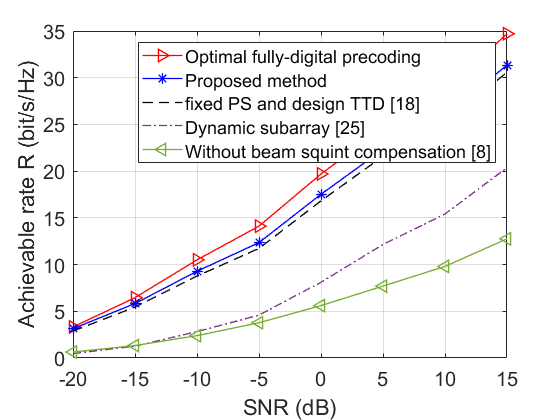

clc;
clear all;
load RateSet1.mat;
load RateConventional.mat;
P = -20:5:15;% transmit power in dB
set(0, 'defaultlinelinewidth', 1); set(0, 'defaultlinemarkersize', 8);
set(0, 'defaultaxesfontsize', 15); set(0, 'defaulttextfontsize', 15); 
plot(P,Rate1,'->r',P,Rate2,'-*b',P,Rate3,'--k',P,Rate4,'-.',P,Rate5,'-<')
grid on 
xlabel('SNR (dB)')
xlim([-20 15])
ylabel('Achievable rate R (bit/s/Hz)')
legend('Optimal fully-digital precoding','Proposed method','fixed PS and design TTD [18]','Dynamic subarray [25]','Without beam squint compensation [8]');

Rate2./Rate1

ans =     0.9427    0.9031    0.8838    0.8750    0.8897    0.9059    0.9070    0.9033


Rate3./Rate1

ans =     0.8680    0.8439    0.8344    0.8312    0.8540    0.8764    0.8808    0.8812


Rate4./Rate1

ans =     0.1402    0.1965    0.2691    0.3250    0.4118    0.4930    0.5388    0.5872


Rate4./Rate1

ans =     0.1402    0.1965    0.2691    0.3250    0.4118    0.4930    0.5388    0.5872


sum(Rate2./Rate1)/length(P)

ans = 0.9013

sum(Rate3./Rate1)/length(P)

ans = 0.8587

sum(Rate4./Rate1)/length(P)

ans = 0.3702

sum(Rate4./Rate1)/length(P)

ans = 0.3702